clear all;
clc

fileID = fopen('erie.txt','r');
formatSpec = '%d %f';
sizeA = [2 Inf];
erie = fscanf(fileID,formatSpec,sizeA);
erie = erie';

fileID = fopen('huron.txt','r');
huron = fscanf(fileID,formatSpec,sizeA);
huron = huron';

fileID = fopen('ontario.txt','r');
ontario = fscanf(fileID,formatSpec,sizeA);
ontario = ontario';

fileID = fopen('michigan.txt','r');
michigan = fscanf(fileID,formatSpec,sizeA);
michigan = michigan'; 

fileID = fopen('superior.txt','r');
superior = fscanf(fileID,formatSpec,sizeA);
superior = superior';

alldata = [ erie, huron(:,2),michigan(:,2),ontario(:,2),superior(:,2)];

for i=2:6
swim_day(i,1) = length(find(alldata(:,i)>20));
end

X = swim_day(2:6);
labels = {'Erie','Huron','Michigan','Ontario','Superior'};
pie(X,labels)

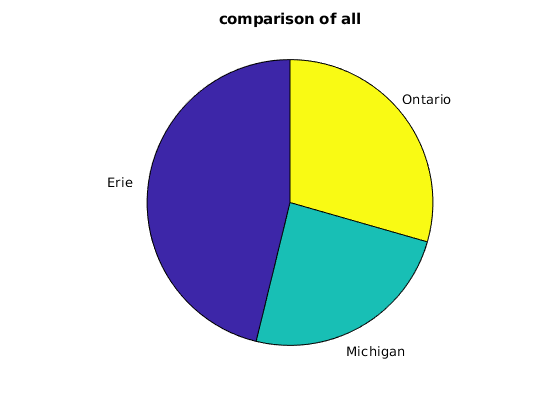

title('comparison of all');

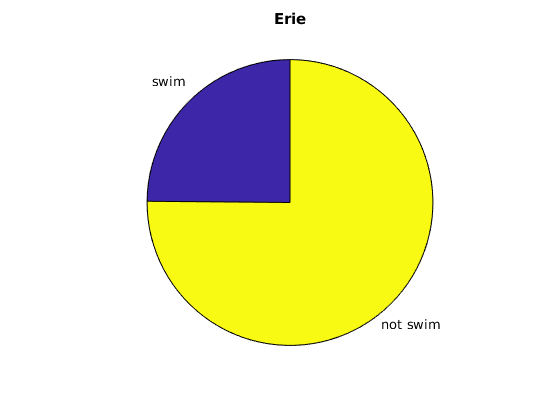


figure;
s = swim_day(2,1);
X = [s,366-s];
labels = {'swim','not swim'};
pie(X,labels)
title('Erie');


figure;
s = swim_day(3,1);
X = [s,366-s];
pie(X,labels)

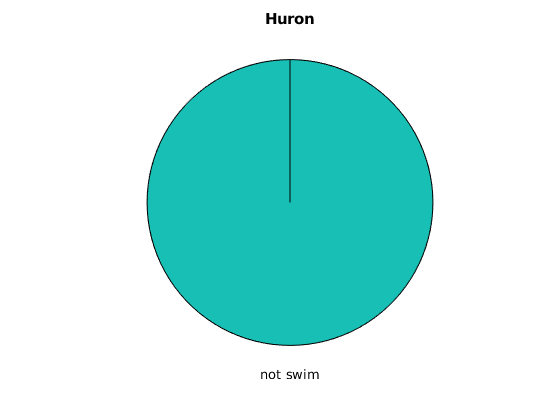

title('Huron');

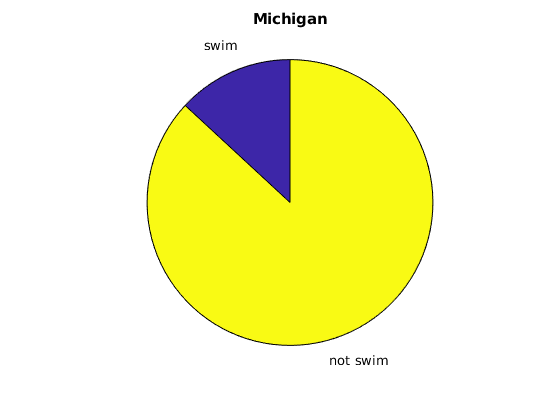


figure;
s = swim_day(4,1);
X = [s,366-s];
pie(X,labels)
title('Michigan');

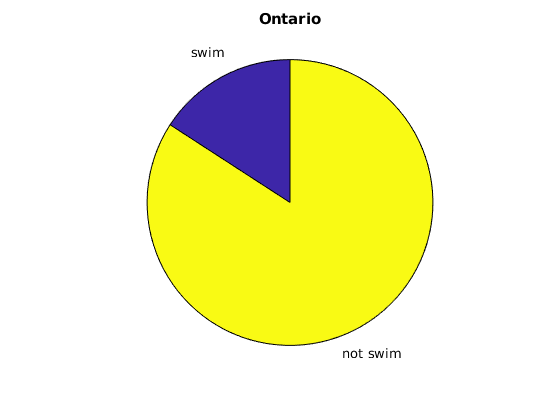


figure;
s = swim_day(5,1);
X = [s,366-s];
pie(X,labels)
title('Ontario');


figure;
s = swim_day(6,1);
X = [s,366-s];
pie(X,labels)

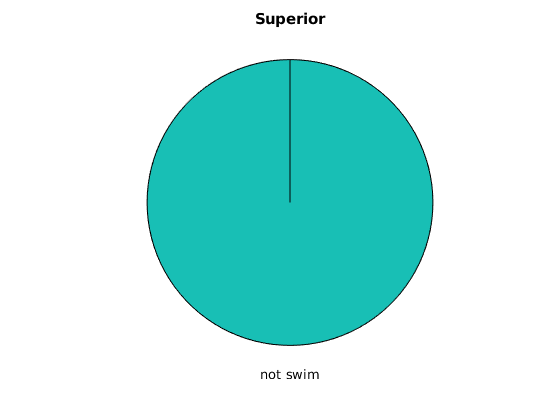

title('Superior');

## Fitting a single equation to all

figure;
plot(alldata(:,1),alldata(:,2),'m', 'linewidth' , 1);
hold on, grid on, box on
plot(alldata(:,1),alldata(:,3),'b', 'linewidth' , 1);
hold on, grid on, box on
plot(alldata(:,1),alldata(:,4),'g', 'linewidth' , 1);
hold on, grid on, box on
plot(alldata(:,1),alldata(:,5),'k', 'linewidth' , 1);
hold on, grid on, box on
plot(alldata(:,1),alldata(:,6),'y', 'linewidth' , 1);
hold on, grid on, box on


avg_temp = mean(alldata(:,2:6)')';
f = fit(alldata(:,1),avg_temp,'poly9');

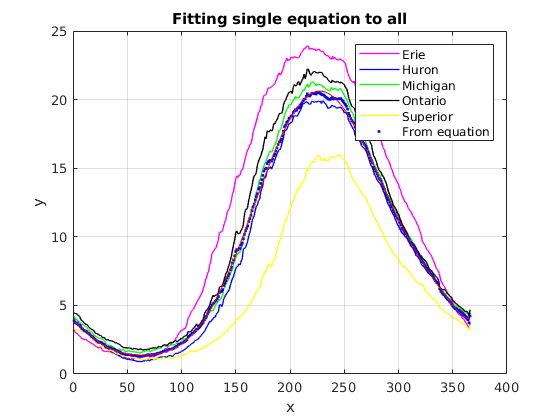

plot(f,alldata(:,1),avg_temp);
legend('Erie','Huron','Michigan','Ontario','Superior','From equation')
title('Fitting single equation to all');

## Individual fitting the equations

figure;
f1=fit(alldata(:,1),alldata(:,2),'poly9')

f1 =      Linear model Poly9:
     f1(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -1.018e-19  (-1.416e-19, -6.191e-20)
       p2 =   2.063e-16  (1.404e-16, 2.722e-16)
       p3 =  -1.748e-13  (-2.206e-13, -1.29e-13)
       p4 =   7.959e-11  (6.223e-11, 9.695e-11)
       p5 =  -2.074e-08  (-2.464e-08, -1.684e-08)
       p6 =   3.041e-06  (2.512e-06, 3.57e-06)
       p7 =  -0.0002339  (-0.000276, -0.0001918)
       p8 =     0.00922  (0.0074, 0.01104)
       p9 =     -0.1958  (-0.2322, -0.1594)
       p10 =        3.66  (3.422, 3.897)

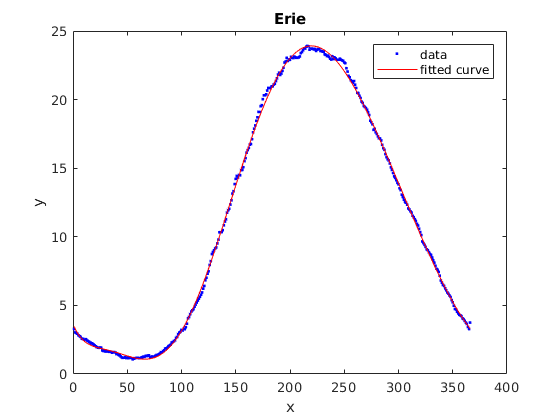

plot(f1,alldata(:,1),alldata(:,2))
title('Erie')


figure;
f2=fit(alldata(:,1),alldata(:,2),'poly9')

f2 =      Linear model Poly9:
     f2(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -1.018e-19  (-1.416e-19, -6.191e-20)
       p2 =   2.063e-16  (1.404e-16, 2.722e-16)
       p3 =  -1.748e-13  (-2.206e-13, -1.29e-13)
       p4 =   7.959e-11  (6.223e-11, 9.695e-11)
       p5 =  -2.074e-08  (-2.464e-08, -1.684e-08)
       p6 =   3.041e-06  (2.512e-06, 3.57e-06)
       p7 =  -0.0002339  (-0.000276, -0.0001918)
       p8 =     0.00922  (0.0074, 0.01104)
       p9 =     -0.1958  (-0.2322, -0.1594)
       p10 =        3.66  (3.422, 3.897)

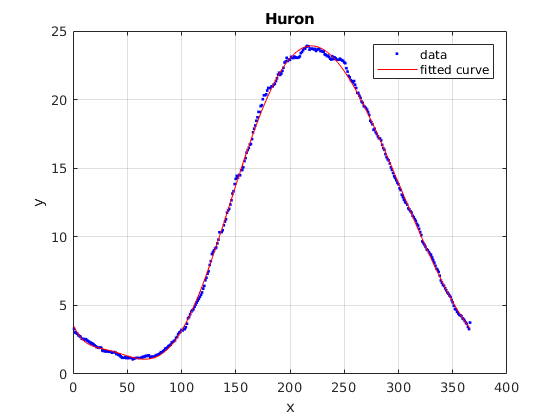

plot(f2,alldata(:,1),alldata(:,2))
grid on, box on
title('Huron')


figure;
f3=fit(alldata(:,1),alldata(:,2),'poly9')

f3 =      Linear model Poly9:
     f3(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -1.018e-19  (-1.416e-19, -6.191e-20)
       p2 =   2.063e-16  (1.404e-16, 2.722e-16)
       p3 =  -1.748e-13  (-2.206e-13, -1.29e-13)
       p4 =   7.959e-11  (6.223e-11, 9.695e-11)
       p5 =  -2.074e-08  (-2.464e-08, -1.684e-08)
       p6 =   3.041e-06  (2.512e-06, 3.57e-06)
       p7 =  -0.0002339  (-0.000276, -0.0001918)
       p8 =     0.00922  (0.0074, 0.01104)
       p9 =     -0.1958  (-0.2322, -0.1594)
       p10 =        3.66  (3.422, 3.897)

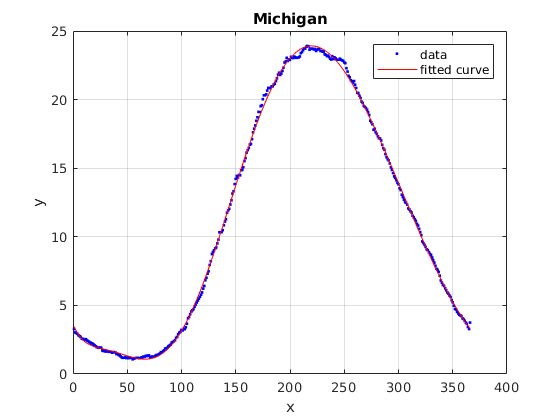

plot(f3,alldata(:,1),alldata(:,2))
grid on, box on
title('Michigan')


figure;
f4=fit(alldata(:,1),alldata(:,2),'poly9')

f4 =      Linear model Poly9:
     f4(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -1.018e-19  (-1.416e-19, -6.191e-20)
       p2 =   2.063e-16  (1.404e-16, 2.722e-16)
       p3 =  -1.748e-13  (-2.206e-13, -1.29e-13)
       p4 =   7.959e-11  (6.223e-11, 9.695e-11)
       p5 =  -2.074e-08  (-2.464e-08, -1.684e-08)
       p6 =   3.041e-06  (2.512e-06, 3.57e-06)
       p7 =  -0.0002339  (-0.000276, -0.0001918)
       p8 =     0.00922  (0.0074, 0.01104)
       p9 =     -0.1958  (-0.2322, -0.1594)
       p10 =        3.66  (3.422, 3.897)

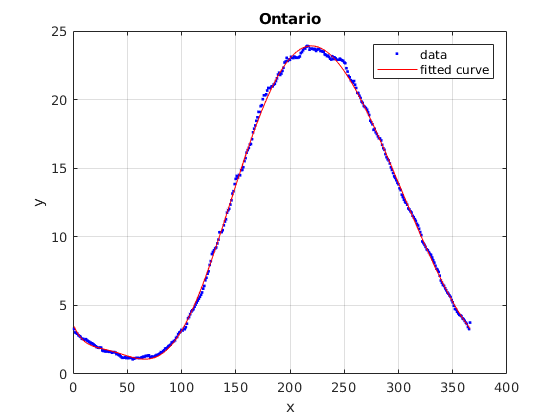

plot(f4,alldata(:,1),alldata(:,2))
grid on, box on
title('Ontario')


figure;
f5=fit(alldata(:,1),alldata(:,2),'poly9')

f5 =      Linear model Poly9:
     f5(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -1.018e-19  (-1.416e-19, -6.191e-20)
       p2 =   2.063e-16  (1.404e-16, 2.722e-16)
       p3 =  -1.748e-13  (-2.206e-13, -1.29e-13)
       p4 =   7.959e-11  (6.223e-11, 9.695e-11)
       p5 =  -2.074e-08  (-2.464e-08, -1.684e-08)
       p6 =   3.041e-06  (2.512e-06, 3.57e-06)
       p7 =  -0.0002339  (-0.000276, -0.0001918)
       p8 =     0.00922  (0.0074, 0.01104)
       p9 =     -0.1958  (-0.2322, -0.1594)
       p10 =        3.66  (3.422, 3.897)

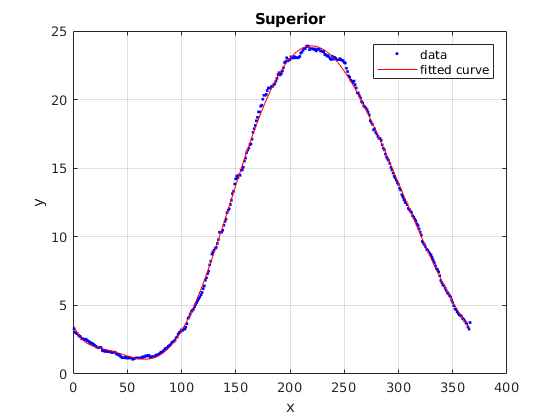

plot(f5,alldata(:,1),alldata(:,2))
grid on, box on
title('Superior')